# 5G NR-TM and FRC Waveform Generation

This example shows how to generate standard-compliant 5G NR test models (NR-TMs) and uplink and downlink fixed reference channels (FRCs) for frequency range 1 (FR1) and frequency range 2 (FR2). For the NR-TM and FRC waveform generation, you can specify the NR-TM or FRC name, the channel bandwidth, the subcarrier spacing, and the duplexing mode.  

## Introduction

The 3GPP 5G NR standard defines sets of link and waveform configurations for the purposes of conformance testing. Two specific types of downlink conformance waveforms are NR test models (NR-TM), for the purpose of base station (BS) RF testing, and downlink fixed reference channels (FRC), for user equipment (UE) input testing.

The NR-TMs for FR1 are defined in [TS 38.141-1](https://www.3gpp.org/ftp/Specs/archive/38_series/38.141-1) Section 4.9.2, and the NR-TMs for FR2 are defined in [TS 38.141-2](https://www.3gpp.org/ftp/Specs/archive/38_series/38.141-2) Section 4.9.2.

They are used in a range of RF tests, including:

- BS output power

- Timing alignment error (TAE)

- Occupied bandwidth emissions

- Adjacent channel leakage ratio (ACLR)

- Operating band unwanted emissions

- Transmitter spurious emissions

- Transmitter intermodulation

Specific test models are aimed at specific sets of measurements.

The physical downlink shared channel (PDSCH) FRC for FR1 are defined in [TS 38.101-1](https://www.3gpp.org/ftp/Specs/archive/38_series/38.101-1) Annex A.3, and for FR2 are defined in [TS 38.101-2](https://www.3gpp.org/ftp/Specs/archive/38_series/38.101-2) Annex A.3.

They are used in a number of UE tests, including:

- UE receiver requirements

- Maximum UE input level testing

The physical uplink shared channel (PUSCH) FRC for FR1 and FR2 are defined in [TS 38.104](https://www.3gpp.org/ftp/Specs/archive/38_series/38.104) Annex A.

They are used in a number of base station reception tests, including:

- Reference sensitivity

- Adjacent channel selectivity (ACS)

- In-band and out-of-band blocking

- Receiver intermodulation

- In-channel selectivity

- Dynamic range

- Performance requirements

NR-TMs and FRCs are defined across a standardized set of transmission bandwidth configurations for a valid range of channel bandwidth and subcarrier spacing combinations.

This reference application example uses the MATLAB class `hNRReferenceWaveformGenerator`. This class provides access to the bandwidth configuration tables, the Release 15 test model and FRC lists, and provides baseband waveform generation and resource grid visualization. 

The `hNRReferenceWaveformGenerator` class contains two constant MATLAB table properties. The `FR1BandwidthTable` property contains the FR1 transmission bandwidth configurations defined in [TS 38.104](https://www.3gpp.org/ftp/Specs/archive/38_series/38.104) Table 5.3.2-1. See also the FR1 maximum transmission bandwidth configurations defined in [TS 38.101-1](https://www.3gpp.org/ftp/Specs/archive/38_series/38.101-1) Table 5.3.2-1. The `FR2BandwidthTable` property contains the FR2 transmission bandwidth configurations defined in [TS 38.104](https://www.3gpp.org/ftp/Specs/archive/38_series/38.104) Table 5.3.2-2. See also the FR2 maximum transmission bandwidth configurations defined in [TS 38.101-2](https://www.3gpp.org/ftp/Specs/archive/38_series/38.101-2) Table 5.3.2-1.

% Release 15 transmission bandwidth configurations
fr1bandwidthtable = hNRReferenceWaveformGenerator.FR1BandwidthTable

fr1bandwidthtable = 3×12 table
             5MHz    10MHz    15MHz    20MHz    25MHz    30MHz    40MHz    50MHz    60MHz    80MHz    90MHz    100MHz
             ____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    ______

    15kHz     25      52       79       106      133      160      216      270      NaN      NaN      NaN      NaN  
    30kHz     11      24       38        51       65       78      106      133      162      217      245      273  
    60kHz    NaN      11       18        24       31       38       51       65       79      107      121      135  


fr2bandwidthtable = hNRReferenceWaveformGenerator.FR2BandwidthTable

fr2bandwidthtable = 2×4 table
              50MHz    100MHz    200MHz    400MHz
              _____    ______    ______    ______

    60kHz      66       132       264       NaN  
    120kHz     32        66       132       264  


The `hNRReferenceWaveformGenerator` class also contains two constant properties which list the test model names for FR1 ([TS 38.141-1](https://www.3gpp.org/ftp/Specs/archive/38_series/38.141-1) Section 4.9.2) and test model names for FR2 ([TS 38.141-2](https://www.3gpp.org/ftp/Specs/archive/38_series/38.141-2) Section 4.9.2).

% Release 15 NR-TM test models for FR1 and FR2 
fr1testmodels = hNRReferenceWaveformGenerator.FR1TestModels

fr1testmodels = 8×1 string 数组
    "NR-FR1-TM1.1"
    "NR-FR1-TM1.2"
    "NR-FR1-TM2"
    "NR-FR1-TM2a"
    "NR-FR1-TM3.1"
    "NR-FR1-TM3.1a"
    "NR-FR1-TM3.2"
    "NR-FR1-TM3.3"


fr2testmodels = hNRReferenceWaveformGenerator.FR2TestModels

fr2testmodels = 3×1 string 数组
    "NR-FR2-TM1.1"
    "NR-FR2-TM2"
    "NR-FR2-TM3.1"


For the downlink FRCs, the class contains additional constant properties which list the downlink FRC names for FR1 ([TS 38.101-1](https://www.3gpp.org/ftp/Specs/archive/38_series/38.101-1) Annex A.3) and for FR2 ([TS 38.101-2](https://www.3gpp.org/ftp/Specs/archive/38_series/38.101-2) Annex A.3).

% Release 15 downlink fixed reference channels for FR1 and FR2 
fr1downlinkfrc = hNRReferenceWaveformGenerator.FR1DownlinkFRC

fr1downlinkfrc = 3×1 string 数组
    "DL-FRC-FR1-QPSK"
    "DL-FRC-FR1-64QAM"
    "DL-FRC-FR1-256QAM"


fr2downlinkfrc = hNRReferenceWaveformGenerator.FR2DownlinkFRC

fr2downlinkfrc = 3×1 string 数组
    "DL-FRC-FR2-QPSK"
    "DL-FRC-FR2-16QAM"
    "DL-FRC-FR2-64QAM"


For the uplink FRCs, the class contains two constant properties which list the uplink FRC names for FR1 and FR2 ([TS 38.104](https://www.3gpp.org/ftp/Specs/archive/38_series/38.104) Annex A).

% Release 15 uplink fixed reference channels for FR1 and FR2 
fr1uplinkfrc = hNRReferenceWaveformGenerator.FR1UplinkFRC 

fr1uplinkfrc = 89×1 string 数组
    "G-FR1-A1-1"
    "G-FR1-A1-2"
    "G-FR1-A1-3"
    "G-FR1-A1-4"
    "G-FR1-A1-5"
    "G-FR1-A1-6"
    "G-FR1-A1-7"
    "G-FR1-A1-8"
    "G-FR1-A1-9"
    "G-FR1-A2-1"
    "G-FR1-A2-2"
    "G-FR1-A2-3"
    "G-FR1-A2-4"
    "G-FR1-A2-5"
    "G-FR1-A2-6"
    "G-FR1-A3-1"
    "G-FR1-A3-2"
    "G-FR1-A3-3"
    "G-FR1-A3-4"
    "G-FR1-A3-5"
    "G-FR1-A3-6"
    "G-FR1-A3-7"
    "G-FR1-A3-8"
    "G-FR1-A3-9"
    "G-FR1-A3-10"
    "G-FR1-A3-11"
    "G-FR1-A3-12"
    "G-FR1-A3-13"
    "G-FR1-A3-14"
    "G-FR1-A3-15"


fr2uplinkfrc = hNRReferenceWaveformGenerator.FR2UplinkFRC

fr2uplinkfrc = 37×1 string 数组
    "G-FR2-A1-1"
    "G-FR2-A1-2"
    "G-FR2-A1-3"
    "G-FR2-A1-4"
    "G-FR2-A1-5"
    "G-FR2-A3-1"
    "G-FR2-A3-2"
    "G-FR2-A3-3"
    "G-FR2-A3-4"
    "G-FR2-A3-5"
    "G-FR2-A3-6"
    "G-FR2-A3-7"
    "G-FR2-A3-8"
    "G-FR2-A3-9"
    "G-FR2-A3-10"
    "G-FR2-A3-11"
    "G-FR2-A3-12"
    "G-FR2-A4-1"
    "G-FR2-A4-2"
    "G-FR2-A4-3"
    "G-FR2-A4-4"
    "G-FR2-A4-5"
    "G-FR2-A4-6"
    "G-FR2-A4-7"
    "G-FR2-A4-8"
    "G-FR2-A4-9"
    "G-FR2-A4-10"
    "G-FR2-A5-1"
    "G-FR2-A5-2"
    "G-FR2-A5-3"


For more information, access the help of `hNRReferenceWaveformGenerator` by typing `'doc hNRReferenceWaveformGenerator'`.

## NR-TM and PDSCH FRC Waveform Generation

Each PDSCH reference waveform is defined by a combination of: 

- NR-TM or FRC name

- Channel bandwidth

- Subcarrier spacing

- Duplexing mode

Different NR-TMs are defined for FR1 and FR2. Depending on the test model purposes, NR-TMs have varying PDSCH characteristics. For example: full band, single modulation scheme, or full band, multiple modulation schemes with varying power boosting/deboosting or single, varying PRB allocation. Common features to all NR-TMs are: no SS burst, PDSCH mapping type A with one (FR2) or two (FR1) DM-RS positions per slot transmission, and a single PDCCH across two symbols with NCCE = 1. There is no transport or DCI coding used and the input to the PDSCH and PDCCH is all 0's. FDD NR-TM waveforms are 10 ms in length and TDD cases are 20 ms. PT-RS are specified for FR2 NR-TM.

By comparison, downlink FRC waveforms contain transport coded PDSCH using RV = 0. The reference PDSCH are not defined in slots which overlap the SS burst (slot 0 or slots 0 and 1). They use front loaded PDSCH mapping type A with 2 additional DM-RS positions. There is no FDM between the PDSCH and the DM-RS. The full-band PDSCH start at symbol 2 and the first 2 symbols in a slot contain a full occupied CORESET. The FRC waveforms generated in this example do not contain additional OCNG. Power levels for all resource elements are uniform. The transport block data source is ITU PN9.

The channel bandwidth and subcarrier spacing combination have to be a valid pair from the associated FR bandwidth configuration table. The standard only defines FR2 NR-TM and FRC for TDD but with this example you can also create FDD waveforms. 

This MATLAB code creates an `hNRReferenceWaveformGenerator` object for the selected NR-TM or FRC configuration. You can use this object to generate the associated baseband waveform and to display the underlying PRB and subcarrier-level resource grids.

% Select the NR-TM or PDSCH FRC waveform parameters
dlnrref = "NR-FR1-TM3.2";  % Model name and properties
bw      = "10MHz";  % Channel bandwidth
scs     = "15kHz";  % Subcarrier spacing
dm      = "FDD";  % Duplexing mode
ncellid = 1;  % NCellID
sv      = "15.2.0";  % TS 38.141-x version (NR-TM only)

% Run this entire section to generate the required waveform
   

% Create generator object for the above NR-TM/PDSCH FRC reference model
dlrefwavegen = hNRReferenceWaveformGenerator(dlnrref,bw,scs,dm,ncellid,sv)

dlrefwavegen =   hNRReferenceWaveformGenerator - 属性:

    FR1BandwidthTable: [3×12 table]
    FR2BandwidthTable: [2×4 table]
        FR1TestModels: [8×1 string]
        FR2TestModels: [3×1 string]
       FR1DownlinkFRC: [3×1 string]
       FR2DownlinkFRC: [3×1 string]
         FR1UplinkFRC: [89×1 string]
         FR2UplinkFRC: [37×1 string]
               Config: [1×1 struct]
           IsReadOnly: 1
      ConfiguredModel: {["NR-FR1-TM3.2"]  ["10MHz"]  ["15kHz"]  ["FDD"]  [1]  ["15.2.0"]}



% Generate waveform
[dlrefwaveform,dlrefwaveinfo,dlresourceinfo] = generateWaveform(dlrefwavegen);

% View transmission information about the set of PDSCH within the waveform
dlresourceinfo.WaveformResources.PDSCH

ans = 包含以下字段的 1×3 struct 数组:
    Name
    CDMLengths
    Resources


% View detailed information about one of the PDSCH sequences
dlresourceinfo.WaveformResources.PDSCH(1).Resources

ans = 包含以下字段的 1×10 struct 数组:
    NSlot
    TransportBlockSize
    TransportBlock
    RV
    Codeword
    G
    Gd
    ChannelIndices
    ChannelSymbols
    DMRSSymbolSet
    DMRSIndices
    DMRSSymbols
    PTRSSymbolSet
    PTRSIndices
    PTRSSymbols


% Waveform sampling rate (Hz)
samplingrate = dlrefwaveinfo.Info.SamplingRate  

samplingrate = 15360000

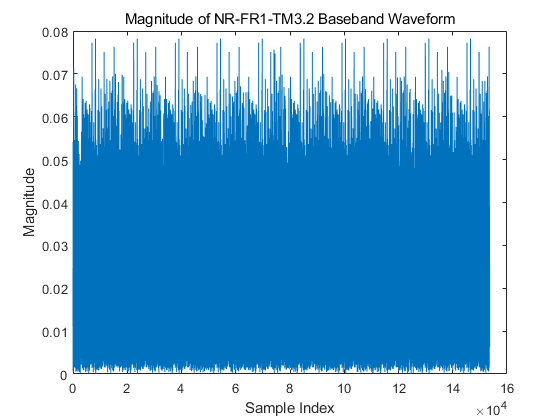


plot(abs(dlrefwaveform)); title(sprintf('Magnitude of %s Baseband Waveform',dlnrref)); xlabel('Sample Index'); ylabel('Magnitude');

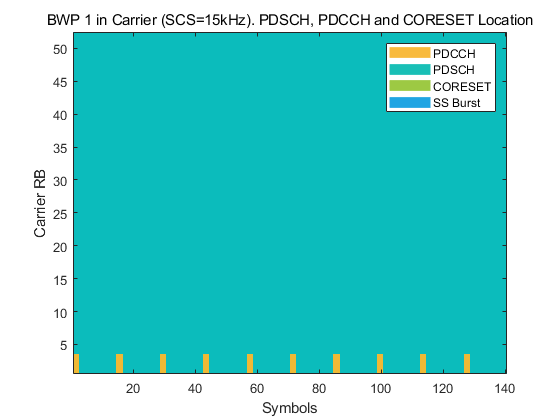

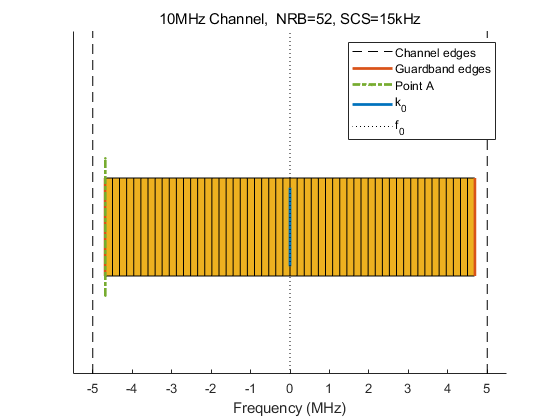

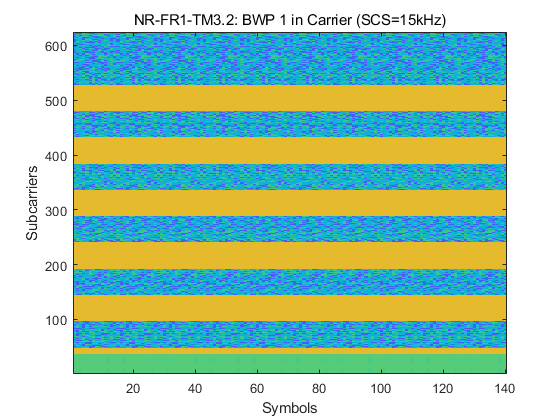


% Visualize the associated PRB and subcarrier resource grids
displayResourceGrid(dlrefwavegen);

fullparameterset = dlrefwavegen.Config   % Full low-level parameter set

fullparameterset = 包含以下字段的 struct :
                Name: "NR-FR1-TM3.2"
             NCellID: 1
    ChannelBandwidth: 10
      FrequencyRange: "FR1"
        NumSubframes: 10
           Windowing: []
        DisplayGrids: 0
             SSBurst: [1×1 struct]
            Carriers: [1×1 struct]
                 BWP: [1×1 struct]
             CORESET: [1×1 struct]
               PDCCH: [1×1 struct]
               CSIRS: [1×1 struct]
               PDSCH: [1×3 struct]



% Make the Config parameters writable and boost the power on all PDSCH DM-RS
dlrefwavegen = makeConfigWritable(dlrefwavegen)

dlrefwavegen =   hNRReferenceWaveformGenerator - 属性:

    FR1BandwidthTable: [3×12 table]
    FR2BandwidthTable: [2×4 table]
        FR1TestModels: [8×1 string]
        FR2TestModels: [3×1 string]
       FR1DownlinkFRC: [3×1 string]
       FR2DownlinkFRC: [3×1 string]
         FR1UplinkFRC: [89×1 string]
         FR2UplinkFRC: [37×1 string]
               Config: [1×1 struct]
           IsReadOnly: 0
      ConfiguredModel: {["NR-FR1-TM3.2"]  ["10MHz"]  ["15kHz"]  ["FDD"]  [1]  ["15.2.0"]}


[dlrefwavegen.Config.PDSCH.PowerDMRS] = deal(3);

## PUSCH FRC Waveform Generation

Each PUSCH FRC reference channel definition in TS 38.104 Annex A explicitly defines a number of key parameters including: 

- Frequency range

- Channel bandwidth

- Subcarrier spacing

- Code rate 

- Modulation

- DM-RS configuration

Additionally, the associated receiver tests introduce some additional parameters that are not specified in the TS 38.104 Annex A tables, for example, the general test parameters defined in:

-  Table 8.2.1.1-1 (Conducted performance requirements for PUSCH without transform precoding)

-  Table 8.2.2.1-1 (Conducted performance requirements for PUSCH with transform precoding)

-  Table 11.2.2.1.1-1 (Radiated performance requirements for BS type 2-O for PUSCH without transform precoding)

-  Table 11.2.2.2.1-1 (Radiated performance requirements for BS type 2-O for PUSCH with transform precoding)

The parameter sets that are captured in the MATLAB reference waveform generator use the above specification sources. Since a given FRC can be used in different tests with different parameters requirements, the following general rules apply to the default generator configurations. All parameters can be modified after construction. Transform precoding is enabled for appropriate FRC. FR2 waveforms are TDD and 20ms in length, and FR1 waveforms are FDD and 10ms. The PUSCH FRC are defined with type A mapping, type B mapping, or, in some cases, either mapping type. In the latter case, type A mapping is configured. FR2 waveforms without transform precoding are configured with PT-RS, otherwise PT-RS are off. Scrambling identities are set to 0. Power levels for all resource elements are uniform. The transport block data source is ITU PN9 with RV = 0 i.e. no retransmissions.

This MATLAB code creates an `hNRReferenceWaveformGenerator` object for the selected PUSCH FRC configuration. Due to the large number of FRC, the live script FRC drop-down lists only those from section TS 38.104 A.1 (reference sensistivity, ACS, in-band blocking etc.) and A.2 (dynamic range). The performance test FRC defined in A.3, A.4, A.5 can be chosen by specifying the FRC name string directly in the code below. After the generator object is created, all configuration parameters can be changed by making them writable using the `makeConfigWritable` function.

% Select the PUSCH FRC waveform 
ulnrref = "G-FR1-A1-1";  % This live script down-drop list is preconfigured for TS 38.104 Annex A.1 and A.2 subsets

% Possible overrides to Annex A definitions (empty values provide the Annex A defaults)
bw      = [];  % Bandwidth override (5,10,15,20,25,30,40,50,60,80,90,100,200,400 MHz)
scs     = [];  % Subcarrier spacing override (15,30,60,120 kHz)
dm      = [];  % Duplexing mode override ("FDD","TDD")
ncellid = [];  % Cell identity override (used to control scrambling identities)

% Run this entire section to generate the required waveform
   

% Create generator object for the above PUSCH FRC reference model
ulrefwavegen = hNRReferenceWaveformGenerator(ulnrref,bw,scs,dm,ncellid)

ulrefwavegen =   hNRReferenceWaveformGenerator - 属性:

    FR1BandwidthTable: [3×12 table]
    FR2BandwidthTable: [2×4 table]
        FR1TestModels: [8×1 string]
        FR2TestModels: [3×1 string]
       FR1DownlinkFRC: [3×1 string]
       FR2DownlinkFRC: [3×1 string]
         FR1UplinkFRC: [89×1 string]
         FR2UplinkFRC: [37×1 string]
               Config: [1×1 struct]
           IsReadOnly: 1
      ConfiguredModel: {["G-FR1-A1-1"]  []  []  ["FDD"]  [0]}



% Generate waveform
[ulrefwaveform,ulrefwaveinfo,ulresourceinfo] = generateWaveform(ulrefwavegen);

% View transmission information about the set of PUSCH within the waveform
ulresourceinfo.WaveformResources.PUSCH

ans = 包含以下字段的 struct :
          Name: "PUSCH sequence for G-FR1-A1-1"
    CDMLengths: [1 1]
     Resources: [1×10 struct]


% View detailed information about one of the PUSCH sequences
ulresourceinfo.WaveformResources.PUSCH(1).Resources

ans = 包含以下字段的 1×10 struct 数组:
    NSlot
    TransportBlockSize
    TransportBlock
    RV
    Codeword
    G
    Gd
    ChannelIndices
    ChannelSymbols
    DMRSSymbolSet
    DMRSIndices
    DMRSSymbols
    PTRSSymbolSet
    PTRSIndices
    PTRSSymbols


 % Waveform sampling rate (Hz)
samplingrate = ulrefwaveinfo.Info.SamplingRate  

samplingrate = 7680000

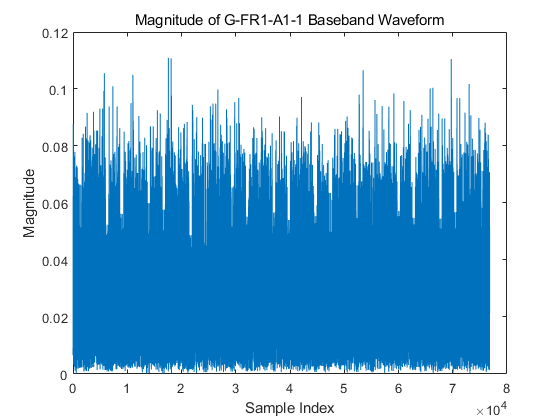

plot(abs(ulrefwaveform)); title(sprintf('Magnitude of %s Baseband Waveform',ulnrref)); xlabel('Sample Index'); ylabel('Magnitude');

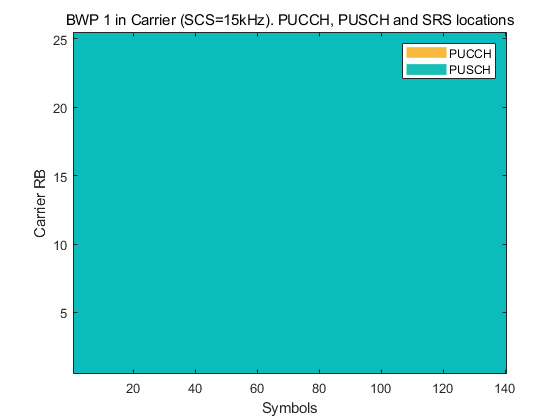

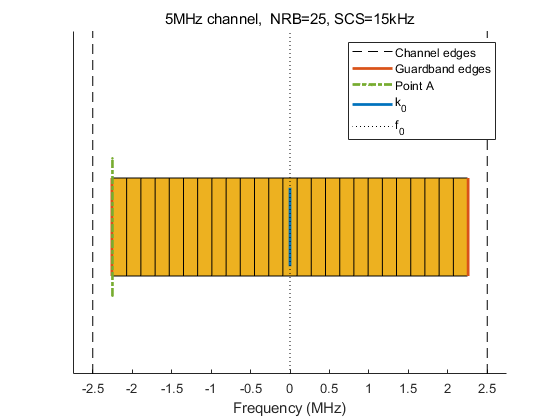

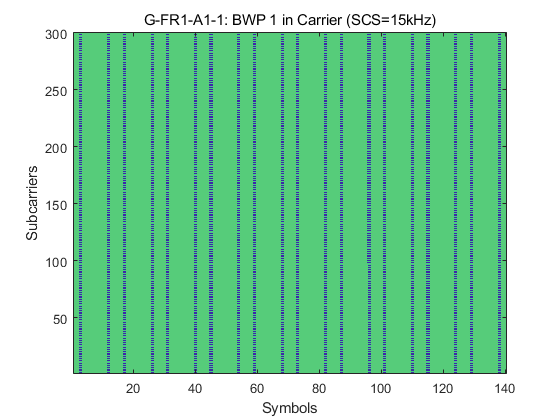


% Visualize the associated PRB and subcarrier resource grids
displayResourceGrid(ulrefwavegen);

fullparameterset = ulrefwavegen.Config   % Full low-level parameter set

fullparameterset = 包含以下字段的 struct :
                Name: 'G-FR1-A1-1'
             NCellID: 0
    ChannelBandwidth: 5
      FrequencyRange: "FR1"
        NumSubframes: 10
           Windowing: []
        DisplayGrids: 0
            Carriers: [1×1 struct]
                 BWP: [1×1 struct]
               PUCCH: [1×1 struct]
               PUSCH: [1×1 struct]


*Copyright 2019-2020 The MathWorks, Inc.*